clc; clear; close all


## Reading and Plotting Radial Data 

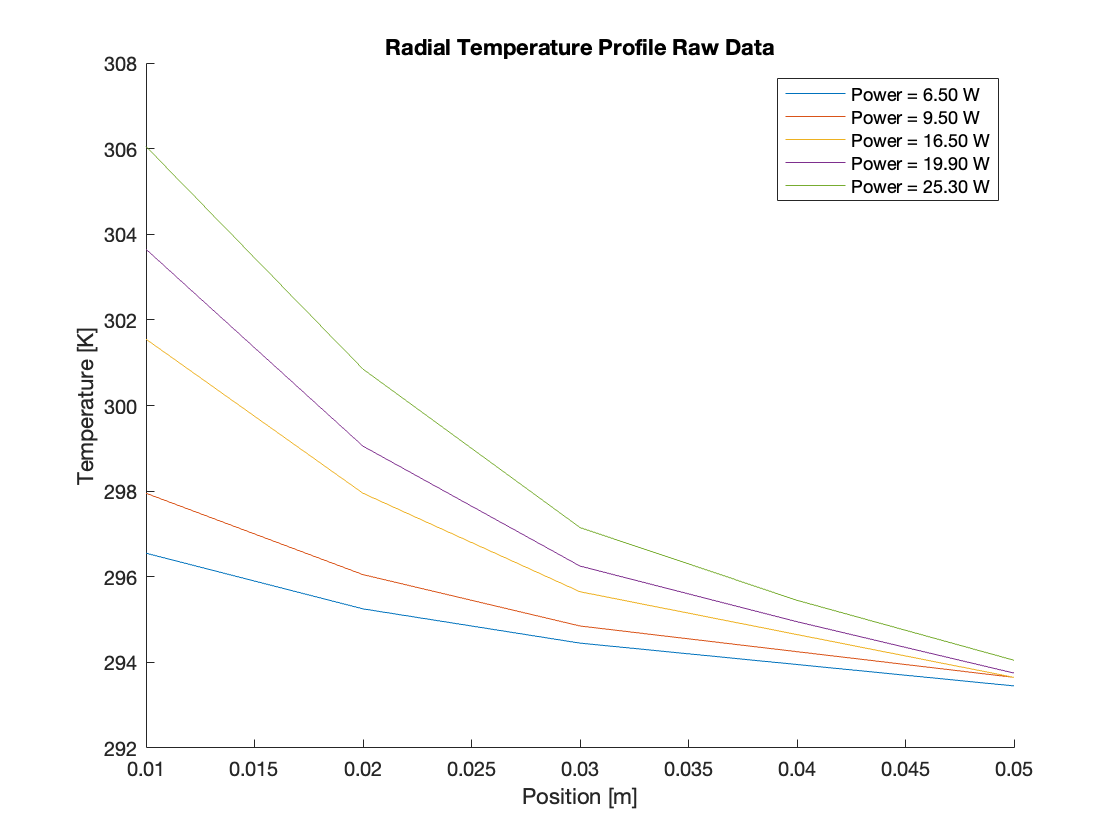

radialData = readmatrix( "Lab 2 Conduction Data (2022).xlsx", "Sheet", "Radial", "Range", "B4:H8" );

[numPower, numCouple] = size( radialData );
numCouple = numCouple - 1; 


rH = 4.0e-3; % m 
L = 3.0e-3; % m
gap = 10e-3; % m 
    
range = 0:gap:( gap * ( numCouple - 1 ) );

names = cell( numPower, 1 );
radialData( :, 2:end ) = radialData( :, 2:end ) + 273.15;
hold on 
for i = 1:numPower 
    names{ i } = sprintf( 'Power = %4.2f W', radialData( i, 1 ) );
    plot( range( 2:end ) , radialData( i, 3:end ) );    
end
legend( names )
title( "Radial Temperature Profile Raw Data")
xlabel( "Position [m]")
ylabel( "Temperature [K]")
hold off 

## Fitting To equation using Radial Data 

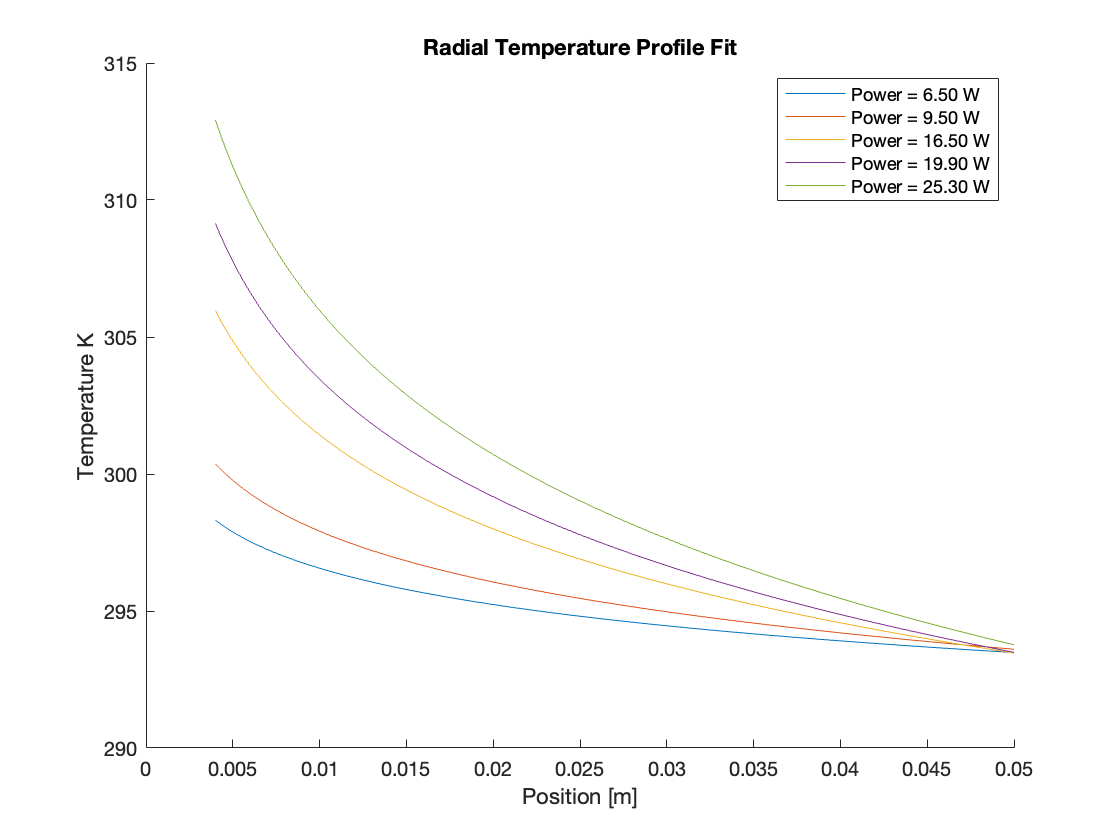

fittingPower = radialData( :, 1 );
fittingTemp = radialData( :, 3:end );

fitEqn = 'a1 - a2 * log( x / 4e-3 )'; 
start = [25 + 273, 2];

fits= cell( numPower, 2 );
a1 = zeros( numPower, 1 );
a2 = zeros( numPower, 1 );
a2_Error = zeros( numPower, 1 );
for i = 1:numPower
    [fits{ i, 1 }, fits{ i, 2 }] = fit( range( 2:end )', fittingTemp( i, : )', fitEqn, 'Start', start );
    a1( i ) = fits{ i, 1 }.a1;
    a2( i ) = fits{ i, 1 }.a2;
    a2_Error( i ) = fits{ i, 2 }.rmse;
end 

k = fittingPower ./ ( 2 .* pi .* a2 .* L );

plotRange = rH:1e-4:range( end );
fitPlots = a1 - ( fittingPower ./ ( 2 .* pi .* k .* L) ) * log( plotRange / rH );


figure() 
hold on 
for i = 1:numPower 
    plot( plotRange, fitPlots( i, : ) )
end
legend( names )
title( "Radial Temperature Profile Fit")
xlabel( "Position [m]")
ylabel( "Temperature K")
hold off 

## Plot with fits and raw 

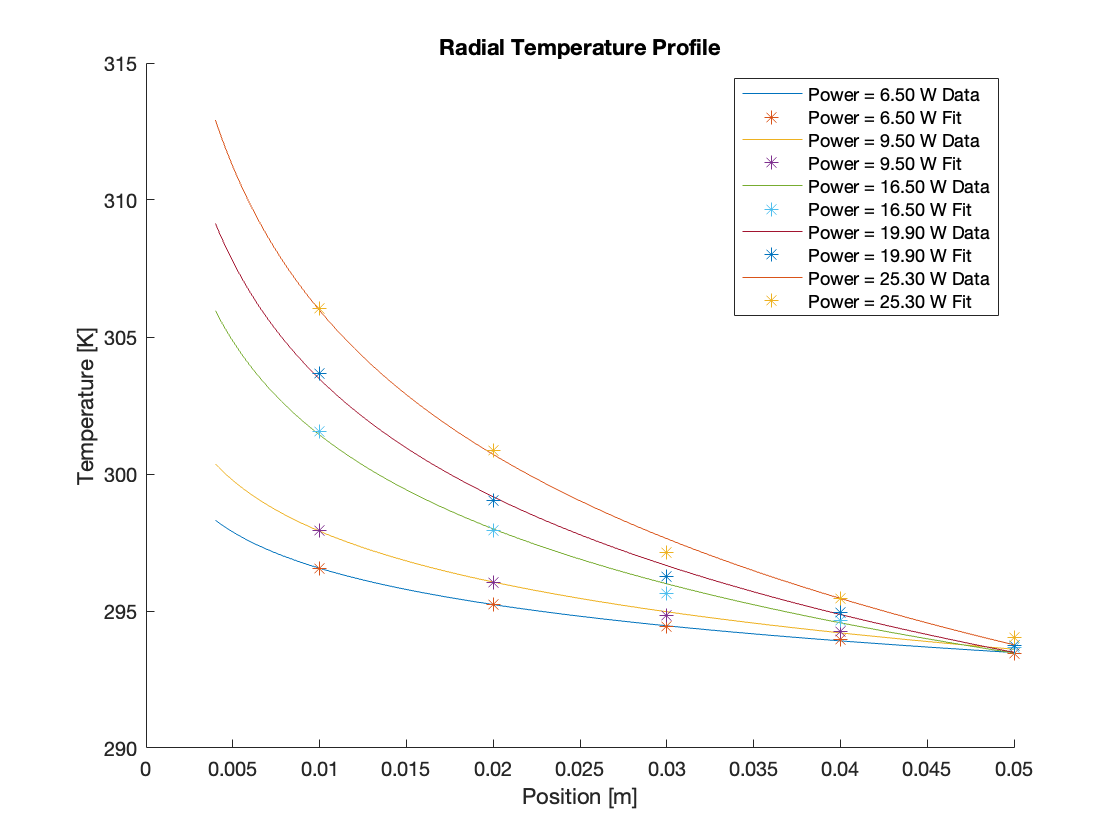

figure() 
names = cell( 2 * numPower, 1 );
hold on 
for i = 1:numPower 
    plot( plotRange, fitPlots( i, : ) )
    plot( range( 2:end ) , radialData( i, 3:end ), '*' );  
    
end

for i = 1:numPower
    names{ 2 * i - 1 } = sprintf( "Power = %4.2f W Data", fittingPower( i ));
    names{ 2 * i } = sprintf( "Power = %4.2f W Fit", fittingPower( i ));
end 
legend( names )
title( "Radial Temperature Profile")
xlabel( "Position [m]")
ylabel( "Temperature [K]")
hold off 

## Error Analysis of k 

dotQ_Error = .5;
syms dotQ a_2
kEqn = dotQ ./ ( 2 .* pi .* a_2 .* L );
[errorFunction, vars, errors, partials] = errorFunc(kEqn)

$$errorFunction = \sqrt{\frac{250000\,{s_{\mathrm{dotQ}}}^{2}}{9\,{a_{2}}^{2}\,\pi^{2}}+\frac{250000\,{\mathrm{dotQ}}^{2}\,{s_{a,2}}^{2}}{9\,{a_{2}}^{4}\,\pi^{2}}}$$

$$vars = \left(\begin{array}{cc} a_{2} & \mathrm{dotQ} \end{array}\right)$$

$$errors = \left(\begin{array}{cc} s_{a,2} & s_{\mathrm{dotQ}} \end{array}\right)$$

$$partials = \left(\begin{array}{cc} -\frac{500\,\mathrm{dotQ}}{3\,{a_{2}}^{2}\,\pi } & \frac{500}{3\,a_{2}\,\pi } \end{array}\right)$$

kErrors = zeros( numPower, 1 );
partialVals = zeros( numPower, 2 );
assignin( "base", sprintf( "%s", errors( 2 ) ), dotQ_Error );

for i = 1:numPower
    assignin( "base", sprintf( "%s", errors( 1 ) ), a2_Error( i ) );
    assignin( "base", sprintf( "%s", vars( 1 ) ), a2( i ) );
    assignin( "base", sprintf( "%s", vars( 2 ) ), fittingPower( i ) );
    kErrors( i ) = vpa( subs( errorFunction ) );
    partialVals( i, 1 ) = vpa( subs( partials( 1 ) ) );
    partialVals( i, 2 ) = vpa( subs( partials( 2 ) ) );
end 


## Pointwise Analysis 

fits = cell( numPower, 2, 4 );
a1_point = zeros( numPower, 4 );
a2_point = zeros( numPower, 4 );

for i = 1:numPower
    for j = 1:4
        [fits{ i, 1, j }, fits{ i, 2, j }] = fit( range( (j+1):(j+2) )', fittingTemp( i, j:j+1 )', fitEqn, 'Start', start );
        a1_point( i, j ) = fits{ i, 1, j }.a1;
        a2_point( i, j ) = fits{ i, 1, j }.a2;
    end 
end 

k_point = fittingPower ./ ( 2 .* pi .* a2_point .* L );


k_pointError =  sqrt( mean( (k - k_point).^2, 2 ) );

kDeviation = std( k );

p = 0.95;
[kMean, kCI] = mean_CI(p, k)

kMean = 178.5890

kCI = 8.0884

radialTable = table( fittingPower, partialVals(:, 1), partialVals(:, 2), k, kErrors)

radialTable = 5×5 table
    fittingPower     Var2       Var3       k       kErrors
    ____________    _______    ______    ______    _______

         6.5        -94.342    27.749    180.37    14.206 
         9.5        -70.314    19.816    188.25    11.501 
        16.5        -35.785    10.727    176.99    10.177 
        19.9        -27.481    8.5593    170.33    9.5133 
        25.3        -23.344    6.9964    177.01    8.6567 


varsTable = table(fittingPower, a1, a2, a2_Error)

varsTable = 5×4 table
    fittingPower      a1        a2      a2_Error
    ____________    ______    ______    ________

         6.5        298.31    1.9118     0.03236
         9.5        300.37    2.6773    0.083053
        16.5        305.96    4.9458      0.2417
        19.9        309.14    6.1981     0.30917
        25.3        312.92    7.5827     0.33921


tableToTex( radialTable, "radial.txt", "Radial Thermal Conductivites", "long")
tableToTex( varsTable, "vars.txt", "Radial Thermal Conductivites", "long")
pointWiseRadial = table( fittingPower, k_point( :, 1 ),  k_point( :, 2 ), k_point( :, 3), k_point( :, 4))

pointWiseRadial = 5×5 table
    fittingPower     Var2      Var3      Var4      Var5 
    ____________    ______    ______    ______    ______

         6.5        183.86    174.77    198.41     153.9
         9.5        183.86    170.29    241.65    187.44
        16.5        168.54    154.32    251.82    195.33
        19.9        159.08    152.88    233.63    196.32
        25.3        178.91    147.09    227.13    213.93


tableToTex( pointWiseRadial, "radk.txt", "Point Wise Thermal Conductivies", "long")
[k_pointMean, k_pointCI] = mean_CI(p, k_point)

k_pointMean = 188.6577

k_pointCI = 14.5982

kPointError = k_pointMean - kMean

kPointError = 10.0687

## Thermal Conductivity as function of mean 

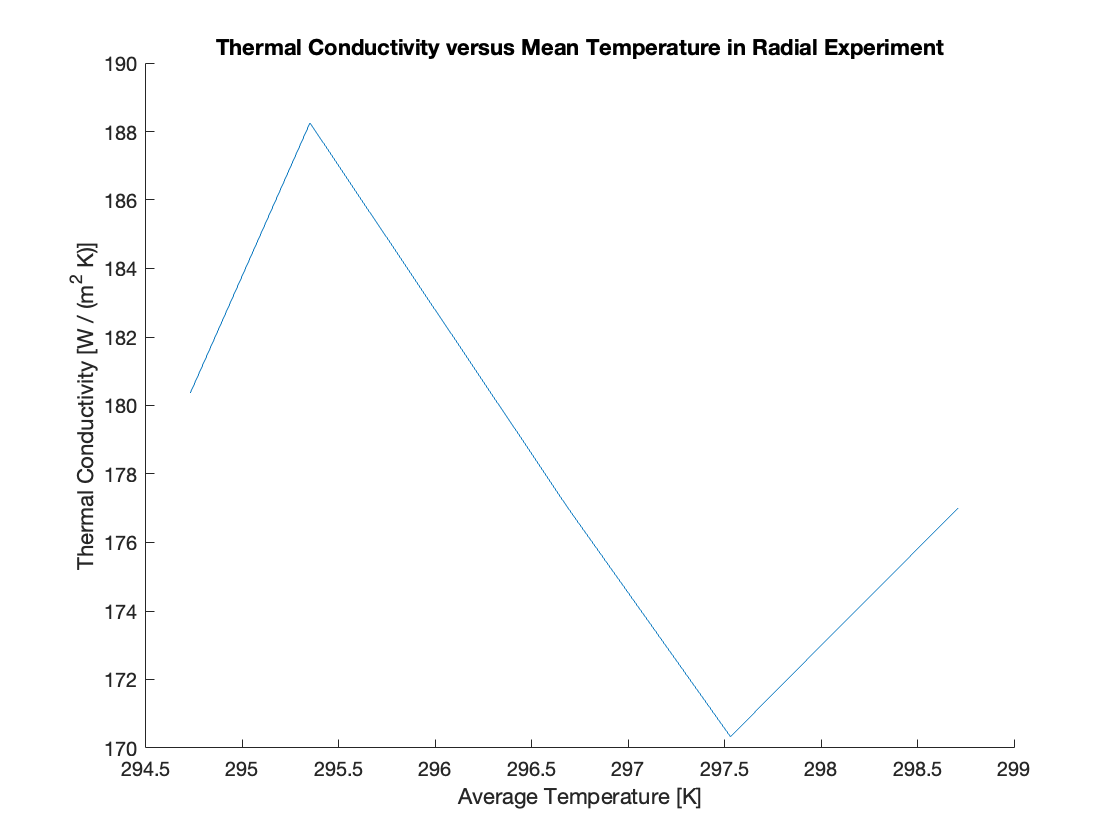

meanTemps = mean( fittingTemp, 2 );
figure() 
hold on
plot( meanTemps, k )
title( "Thermal Conductivity versus Mean Temperature in Radial Experiment")
xlabel( "Average Temperature [K]")
ylabel( "Thermal Conductivity [W / (m^2 K)]")
hold off 

## Axial Data Plotting 

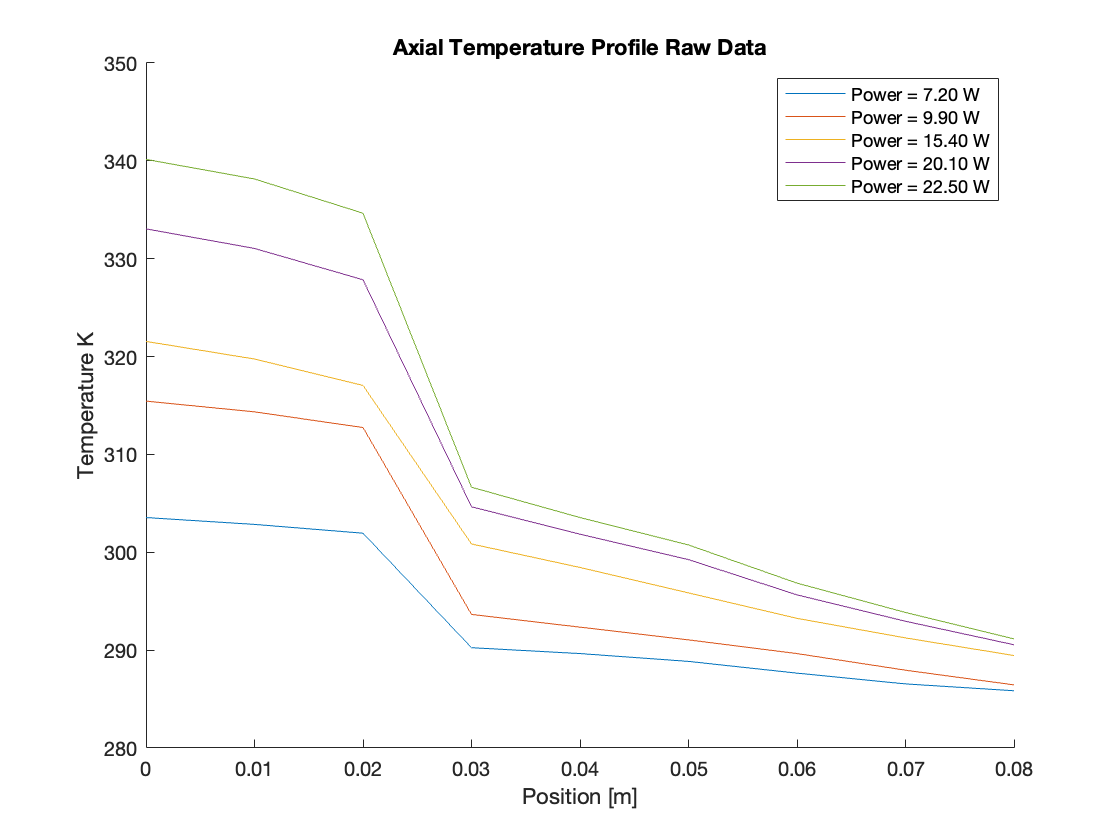

axialPower = readmatrix( "Lab 2 Conduction Data (2022).xlsx", "Sheet", "Axial", "Range", "B4:B8");
axialTemp = readmatrix( "Lab 2 Conduction Data (2022).xlsx", "Sheet", "Axial", "Range", "C4:K8") + 273.15;
[numPower, numTemp] = size( axialTemp );
gap = 10e-3;
range = 0:gap:( numTemp - 1) * gap; 

names = cell( numPower, 1 );
figure() 
hold on 
for i = 1:numPower
    plot( range, axialTemp( i, : ) )
    names{ i } = sprintf( 'Power = %4.2f W', axialPower( i ));
end 
legend( names )
title( "Axial Temperature Profile Raw Data")
xlabel( "Position [m]")
ylabel( "Temperature K")
hold off 

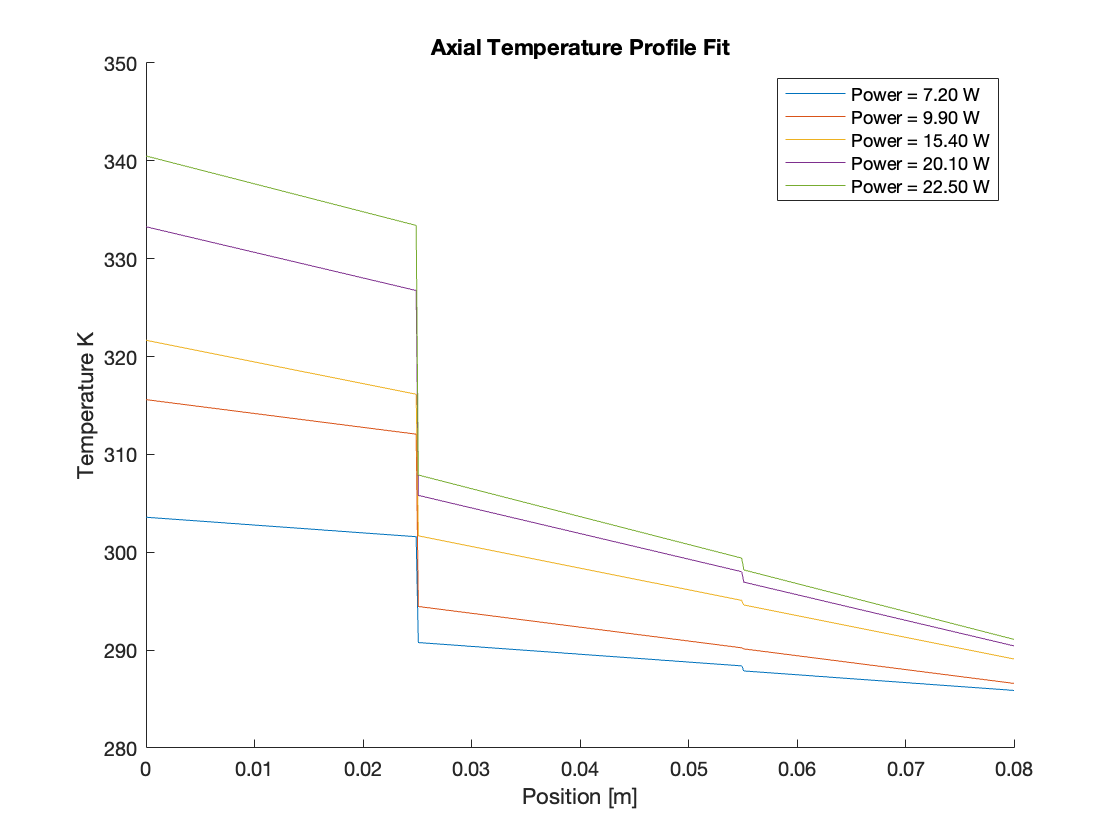

fitEqn = 'a1 - a2 * x - a3 * heaviside( x - 25e-3 ) - a4 * heaviside( x - 55e-3 )';
fits = cell( numPower, 4 );
a1 = zeros( numPower, 1 );
a2 = zeros( numPower, 1 );
a3 = zeros( numPower, 1 );
a4 = zeros( numPower, 1 );
fitErrors = zeros( numPower, 1 );

region1 = range <= 25e-3;
region2 = (range > 25e-3) & (range <= 55e-3);
region3 = range > 55e-3 ;

start = [300; 2; 20; 2];
for i = 1:numPower 
    [fits{ i, 1 }, fits{ i, 2 }] = fit( range', axialTemp( i, :)', fitEqn, 'start', start);
    a1( i ) = fits{ i, 1 }.a1;
    a2( i ) = fits{ i, 1 }.a2;
    a3( i ) = fits{ i, 1 }.a3;
    a4( i ) = fits{ i, 1 }.a4;
    fitErrors( i ) = fits{ i, 2}.rmse;
end 

coefTable = table( axialPower, a1, a2, a3, a4 );
tableToTex( coefTable, "coef.txt", "Table of Fitting Calculated Coefficients", "long")

plotRange = 0:1e-4:range( end );

plotData = a1 - a2 .* plotRange - a3 .* heaviside( plotRange - 25e-3 ) - a4 .* heaviside( plotRange - 55e-3 );

figure() 
hold on 
for i = 1:numPower
    plot( plotRange, plotData( i, :) )
end 
legend( names )
title( "Axial Temperature Profile Fit")
xlabel( "Position [m]")
ylabel( "Temperature K")
hold off 

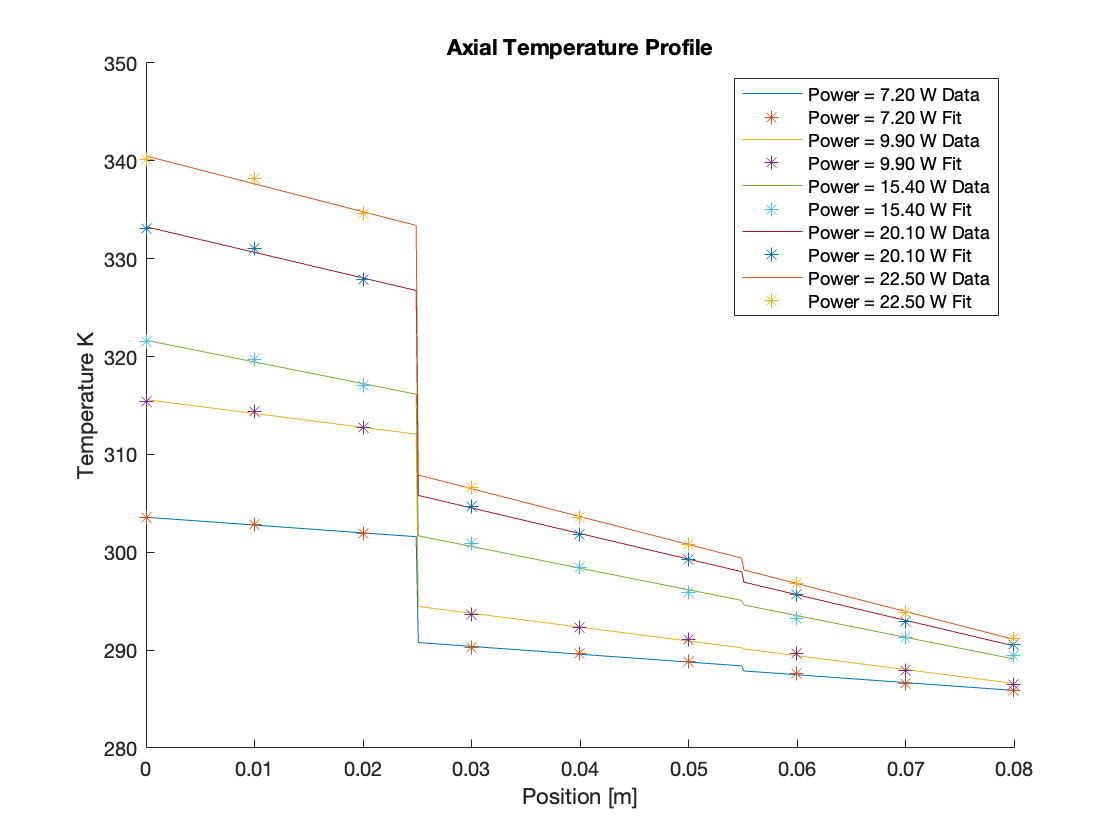


figure() 
hold on 
names = cell( 2 * numPower, 1);
for i = 1:numPower
    plot( plotRange, plotData( i, :) )
    plot( range, axialTemp( i, : ) , '*')

    names{ 2 * i - 1} = sprintf( 'Power = %4.2f W Data', axialPower( i ));
    names{ 2 * i } = sprintf( 'Power = %4.2f W Fit', axialPower( i ));
end 
legend( names )
title( "Axial Temperature Profile")
xlabel( "Position [m]")
ylabel( "Temperature K")
hold off                                                

A_0 = 490.9e-6; 
k = axialPower ./ ( a2 .* A_0 );
HG1 = axialPower ./ ( a3 .* A_0 );
HG2 = axialPower ./ ( a4 .* A_0 );


syms dotQ a_2 a_3 a_4 
kEqn = dotQ ./ ( a_2 .* A_0 );
HG1Eqn = dotQ ./ ( a_3 .* A_0 );
HG2Eqn = dotQ ./ ( a_4 .* A_0 );


[kerrorFunction, kvars, kerrors, kpartials] = errorFunc(kEqn)

$$kerrorFunction = \sqrt{\frac{85070591730234615865843651857942052864\,{s_{\mathrm{dotQ}}}^{2}}{20500550243514695668643656056081\,{a_{2}}^{2}}+\frac{85070591730234615865843651857942052864\,{\mathrm{dotQ}}^{2}\,{s_{a,2}}^{2}}{20500550243514695668643656056081\,{a_{2}}^{4}}}$$

$$kvars = \left(\begin{array}{cc} a_{2} & \mathrm{dotQ} \end{array}\right)$$

$$kerrors = \left(\begin{array}{cc} s_{a,2} & s_{\mathrm{dotQ}} \end{array}\right)$$

$$kpartials = \left(\begin{array}{cc} -\frac{9223372036854775808\,\mathrm{dotQ}}{4527753332892009\,{a_{2}}^{2}} & \frac{9223372036854775808}{4527753332892009\,a_{2}} \end{array}\right)$$

[HG1errorFunction, HG1vars, HG1errors, HG1partials] = errorFunc(HG1Eqn)

$$HG1errorFunction = \sqrt{\frac{85070591730234615865843651857942052864\,{s_{\mathrm{dotQ}}}^{2}}{20500550243514695668643656056081\,{a_{3}}^{2}}+\frac{85070591730234615865843651857942052864\,{\mathrm{dotQ}}^{2}\,{s_{a,3}}^{2}}{20500550243514695668643656056081\,{a_{3}}^{4}}}$$

$$HG1vars = \left(\begin{array}{cc} a_{3} & \mathrm{dotQ} \end{array}\right)$$

$$HG1errors = \left(\begin{array}{cc} s_{a,3} & s_{\mathrm{dotQ}} \end{array}\right)$$

$$HG1partials = \left(\begin{array}{cc} -\frac{9223372036854775808\,\mathrm{dotQ}}{4527753332892009\,{a_{3}}^{2}} & \frac{9223372036854775808}{4527753332892009\,a_{3}} \end{array}\right)$$

[HG2errorFunction, HG2vars, HG2errors, HG2partials] = errorFunc(HG2Eqn)

$$HG2errorFunction = \sqrt{\frac{85070591730234615865843651857942052864\,{s_{\mathrm{dotQ}}}^{2}}{20500550243514695668643656056081\,{a_{4}}^{2}}+\frac{85070591730234615865843651857942052864\,{\mathrm{dotQ}}^{2}\,{s_{a,4}}^{2}}{20500550243514695668643656056081\,{a_{4}}^{4}}}$$

$$HG2vars = \left(\begin{array}{cc} a_{4} & \mathrm{dotQ} \end{array}\right)$$

$$HG2errors = \left(\begin{array}{cc} s_{a,4} & s_{\mathrm{dotQ}} \end{array}\right)$$

$$HG2partials = \left(\begin{array}{cc} -\frac{9223372036854775808\,\mathrm{dotQ}}{4527753332892009\,{a_{4}}^{2}} & \frac{9223372036854775808}{4527753332892009\,a_{4}} \end{array}\right)$$

assignin( "base", sprintf("%s", kerrors( 2 ) ), 0.5);

kError1 = zeros( numPower, 1 );
HG1Error1 = zeros( numPower, 1 );
HG2Error1 = zeros( numPower, 1 );

pValKa2 = zeros( numPower, 1 );
pValKQ = zeros( numPower, 1 );

pValHG1Qdot = zeros( numPower, 1 );
pValHG2Qdot = zeros( numPower, 1 );

for i = 1:numPower
    assignin( "base", "dotQ", axialPower( i ));
    assignin( "base", "a_2", a2( i ));
    assignin( "base", "a_3", a3( i ));
    assignin( "base", "a_4", a4( i ));

    assignin( "base", sprintf("%s", kerrors( 1 ) )  , fitErrors( i ));
    assignin( "base", sprintf("%s", HG1errors( 1 ) ), 0);
    assignin( "base", sprintf("%s", HG2errors( 1 ) ), 0);

    kError1( i ) = vpa( subs( kerrorFunction ) );
    HG1Error1( i ) = vpa( subs( HG1errorFunction ) );
    HG2Error1( i) = vpa( subs( HG2errorFunction ) );
    
    pValKa2( i ) = vpa( subs( kpartials( 1 ) ) );
    pValKQ( i ) = vpa( subs( kpartials( 2 ) ) );

    pValHG1Qdot( i ) = vpa( subs( HG1partials( 2 ) ) );
    pValHG2Qdot( i ) = vpa( subs( HG2partials( 2 ) ) );

end 

axialTable = table( axialPower, k, kError1, HG1, HG1Error1, HG2, HG2Error1)

axialTable = 5×7 table
    axialPower      k       kError1     HG1      HG1Error1       HG2        HG2Error1
    __________    ______    _______    ______    _________    __________    _________

        7.2       183.34    12.735       1358     94.309           29334     2037.1  
        9.9       142.36    7.1918     1146.9     57.926      2.4201e+05      12222  
       15.4       141.52    4.5994       2176      70.65           75290     2444.5  
       20.1       156.48    3.8951     1960.7     48.773           40274     1001.8  
       22.5       160.82    3.5778       1801     40.021           39856     885.68  


tableToTex( axialTable, "axK.txt", "Thermal Conductivity and Thermal Resitence", "long")
axpartialTale = table( axialPower, pValKa2, pValKQ, pValHG1Qdot, pValHG2Qdot)

axpartialTale = 5×5 table
    axialPower    pValKa2     pValKQ    pValHG1Qdot    pValHG2Qdot
    __________    ________    ______    ___________    ___________

        7.2        -2.2917    25.463      188.62         4074.1   
        9.9        -1.0049    14.379      115.85          24445   
       15.4       -0.63845    9.1898       141.3           4889   
       20.1       -0.59801     7.785      97.545         2003.7   
       22.5       -0.56429    7.1476      80.042         1771.4   


tableToTex( axpartialTale, "axPartail.txt", "Thermal Conductivity and Thermal Resitence", "long")
[kMean, kCI] = mean_CI(p, k)

kMean = 156.9031

kCI = 21.1671

[HG1Mean, HG1CI] = mean_CI(p, HG1)

HG1Mean = 1.6885e+03

HG1CI = 529.3035

[HG2Mean, CI] = mean_CI(p, HG2)

HG2Mean = 8.5352e+04

CI = 1.1085e+05

## Point Wise Calculations

kfit = 'a1 - a2 * x';

start = [300; 200];


fits = cell( numPower, 4, ( sum(region1) - 1));
a1 = zeros( numPower, ( sum(region1) - 1) );
a2 = zeros( numPower, ( sum(region1) - 1) );

for i = 1:numPower 
    for j = 1:( sum(region1) - 1)
        [fits{ i, 1, j }, fits{ i, 2, j }] = fit( range( j:j+1 )', axialTemp( i, j:j+1)', kfit, 'start', start);
        a1( i, j ) = fits{ i, 1, j }.a1;
        a2( i, j ) = fits{ i, 1, j }.a2;
        fitErrors( i, j ) = fits{ i, 2, j}.rmse;
    end
end 

kPoint = axialPower ./ ( a2 .* A_0 );
k_pointTable = table( axialPower, kPoint( :, 1 ), kPoint( :, 2 ))

k_pointTable = 5×3 table
    axialPower     Var2      Var3 
    __________    ______    ______

        7.2       209.53    162.97
        9.9       183.34    126.04
       15.4       174.28    116.19
       20.1       204.73    127.95
       22.5       229.17    130.95


tableToTex( k_pointTable, "axpoin.txt", "Thermal Conductivity and Thermal Resitence", "long")
[kPointMean, kPointCI] = mean_CI(p, kPoint)

kPointMean = 166.5152

kPointCI = 28.7273

kPointError = kPointMean - kMean

kPointError = 9.6120

## Thermal Conductivity as function of mean 

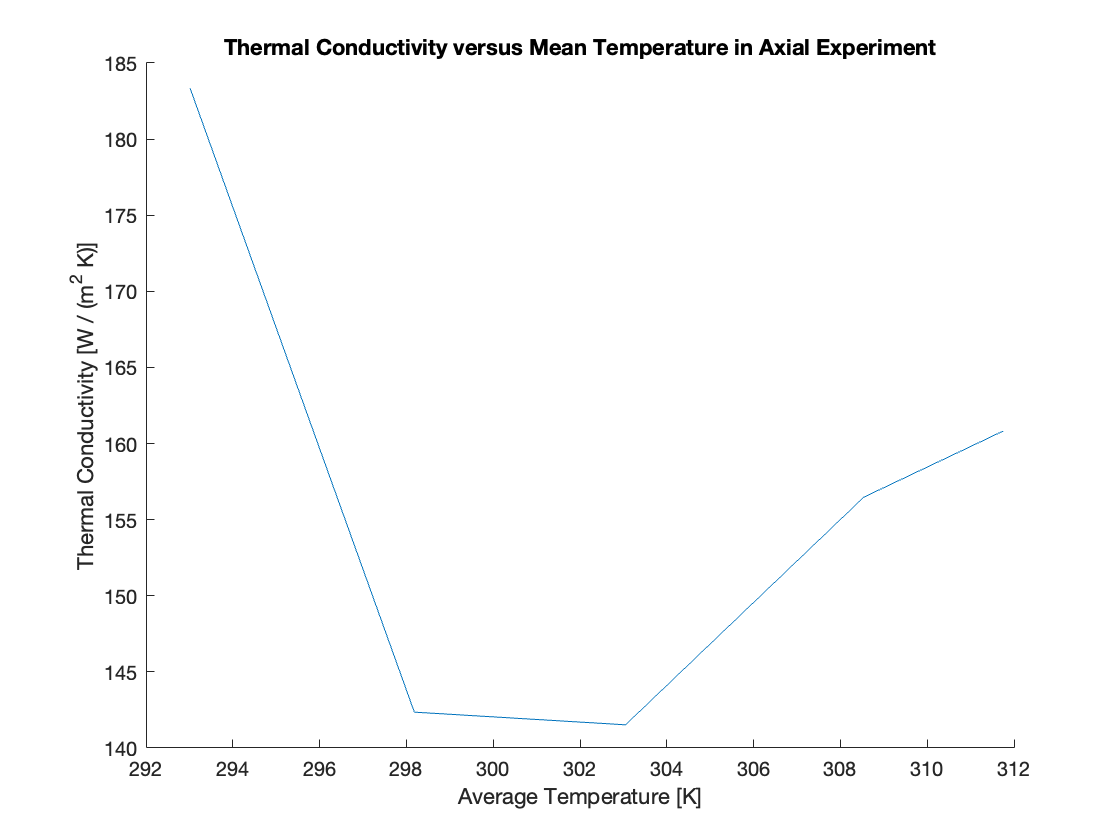

meanTemp = mean( axialTemp, 2 );
figure() 
hold on 
plot( meanTemp, k)
title( "Thermal Conductivity versus Mean Temperature in Axial Experiment")
xlabel( "Average Temperature [K]")
ylabel( "Thermal Conductivity [W / (m^2 K)]")
hold off 